# Q1. Source Free heat conduction across an insulated rod, with ends maintained at specified temperatures.

## By- Anish Dhar, 211020067

- Variable Initialization

L = input("Enter Length of the Rod")

L = 2

K = 1

K = 1

h=input("Enter Convective Heat Transfer coefficient") %convective HT coeff

h = 0

N_points = input("Enter Number of Points")

N_points = 50

Tc = input("Enter Thermal Conductivity");%W/m-K
Q_gen = 1000; % W/m^2
area= 1

area = 1

p=1

p = 1

St = -1

St = -1

Sc = 1000

Sc = 1000

Ti = input("Enter Initial Temperature")

Ti = 100

To=input("Enter Final Temperature")

To = 500

Ta = 30

Ta = 30

m2=((h*p)/(Tc*area))

m2 = 0

- Initializing important parameters for the given problem, 

x = zeros(N_points+2, 1); % For the unit lengths
a = zeros(N_points+2, 1); % For the right side of the matrix diagonal elements
b = zeros(N_points+2, 1); % For the left side of the matrix diagonal elements
d = zeros(N_points+2, 1); % For the diagonal Elements of the matrix
c = zeros(N_points+2, 1); % For the equation's answers

array_temps = zeros(N_points+2, 2); % For the equation's answers

dx = zeros(N_points + 2, 1); %element size assignment
for i = 2:1:N_points+1
dx(i) = L/N_points;
end
dx(1) = L/(N_points * 2);
dx(N_points+2) = L/(N_points * 2);

% disp(dx)
x(1) = 0;
for i = 2:1:N_points+2 %No. of points to plot the results on, based on Dx
x(i) = x(i-1) + dx(i-1);
end

- Generating the matrix, with the necessary values.

% Initial Boundary Conditions
a(1) = 0;
b(1) = 0;
c(1) = Ti;
d(1) = 1;


% Thermal Conductivities for the all but last point.
for i = 2:1:N_points+1
    % disp(i);
    d(i) = -(1/(dx(i-1)) + 1/dx(i+1) + m2); %St
    % disp(d(i));
    a(i) = (1/dx(i+1));
    b(i) = (1/dx(i-1));
    c(i) = -m2*To; %Sc
end

% Final Boundary Conditions
a(N_points + 2) = 0;
b(N_points + 2) = 0;
d(N_points + 2) = 1;
c(N_points + 2) = To;


NUMERICAL SOLUTION:

for i = 2:1:N_points+2
    d(i) = d(i) - b(i)*a(i-1)/d(i-1);
    c(i) = c(i) - b(i)*c(i-1)/d(i-1);
end

%for i = 1:1:N_points+2
%    disp(d(i));
%end

array_temps(N_points+2,1) = c(N_points+2)/d(N_points+2);
array_temps(N_points+2,2) = x(N_points+2);


for i = N_points+1:-1:1
    array_temps(i,1) = (c(i) - a(i)*array_temps(i+1,1))/d(i);
    array_temps(i,2) = x(i);
end

ANALYTICAL SOLUTION:

array_temps_analytical = zeros(N_points+2, 2); 

delta_x = zeros(N_points + 2, 1); 

for i = 2:1:N_points+1 
    delta_x(i) = L/N_points; 
end 
delta_x(1) = L/(N_points * 2); 
delta_x(N_points+2) = L/(N_points * 2); 
x(1) = 0; 
for i = 2:1:N_points+2 % Getting all the points from the delta 
    x(i) = x(i-1) + delta_x(i-1); 
end 

array_temps_analytical(1,1) = Ti; 

for i = 2:1:N_points+2 
    array_temps_analytical(i,1) = array_temps_analytical(i-1) + ((To-Ti)/L)*delta_x(i); 
    array_temps_analytical(i,2) = x(i);  
end 


- Plotting the resulting points:

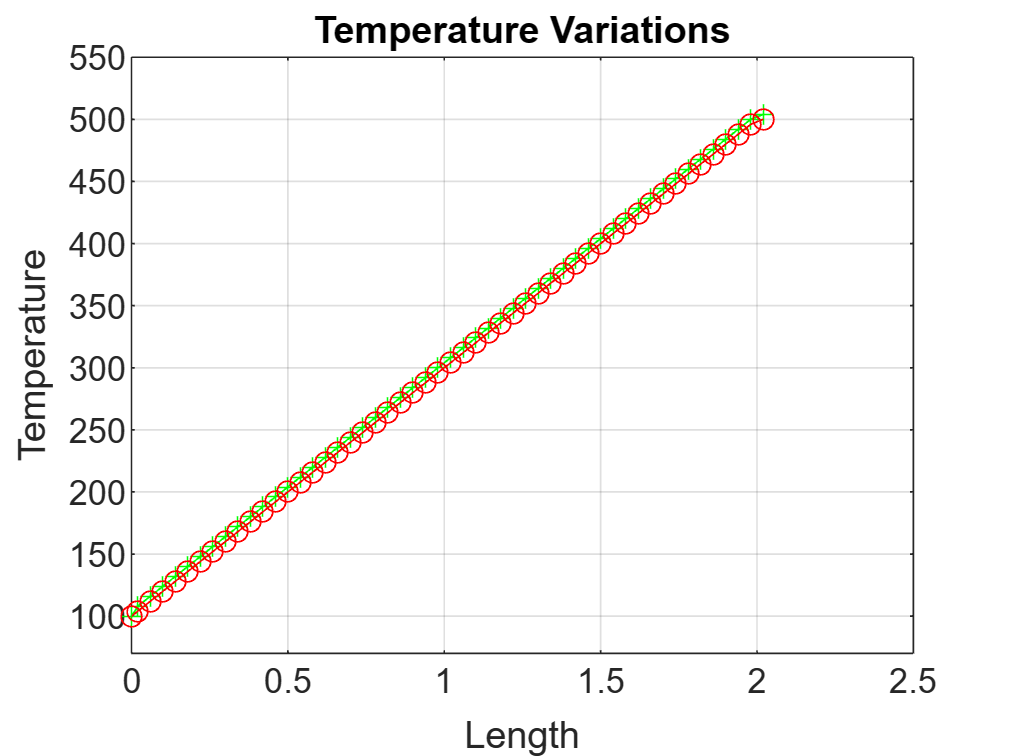

figure;
%for analytical graph
plot(array_temps_analytical(:,2),array_temps_analytical(:,1), 'g+-');
xlabel('Length');
ylabel('Temperature');
title('Temperature Variations');
grid on
hold on
%for numerical solution graph
plot(array_temps(:,2),array_temps(:,1), 'ro-');
xlabel('Length');
ylabel('Temperature');
title('Temperature Variations');
xlim([0 2.5])
ylim([70 550])
grid on
hold off